mapData = load('C:\Users\msi\OneDrive - Óbudai egyetem\0_Szakdolgozat\MATLAB_Scripts\3D\occupancy_map_3d.mat')

mapData = struct with fields:
    omap3D: [1×1 occupancyMap3D]


omap = mapData.omap3D

omap =   occupancyMap3D with properties:

    ProbabilitySaturation: [1.0000e-03 0.9990]
               Resolution: 1
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000


omap.FreeThreshold = omap.OccupiedThreshold;

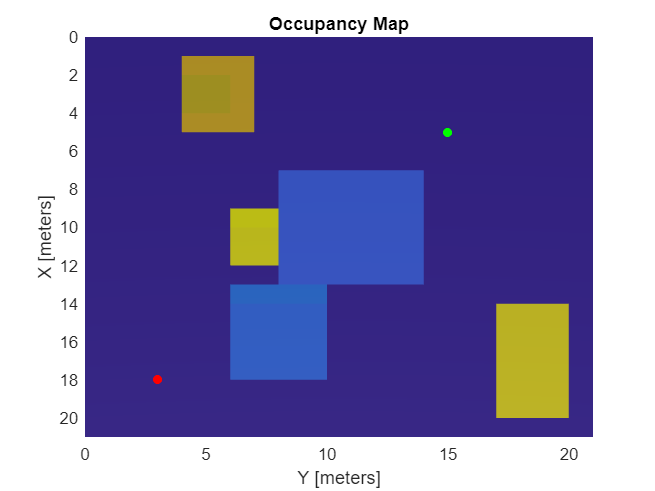

startPose = [18 3 4 pi/2];
goalPose = [5 15 6 pi/2];
figure("Name","StartAndGoal")
hMap = show(omap);
hold on
scatter3(hMap,startPose(1),startPose(2),startPose(3),30,"red","filled")
scatter3(hMap,goalPose(1),goalPose(2),goalPose(3),30,"green","filled")
hold off
view([90 90])

ss = UAVstatespace("MaxRollAngle",pi/6,...
                                "AirSpeed",1,...
                                "FlightPathAngleLimit",[-0.1 0.1],...
                                "Bounds",[0 20; 0 20; 0.5 100; -pi pi]);
threshold = [(goalPose-0.5)' (goalPose+0.5)'; -pi pi];
sv = validatorOccupancyMap3D(ss,"Map",omap);
sv.ValidationDistance = 0.1;


planner = plannerRRT(ss,sv);
planner.MaxConnectionDistance = 5;
planner.GoalBias = 0.10;  
planner.MaxIterations = 400;
planner.GoalReachedFcn = @(~,x,y)(norm(x(1:3)-y(1:3)) < 2);

[pthObj,solnInfo] = plan(planner,startPose,goalPose)

pthObj =   navPath with properties:

      StateSpace: [1×1 UAVstatespace]
          States: [7×4 double]
       NumStates: 7
    MaxNumStates: Inf


solnInfo = struct with fields:
      IsPathFound: 1
         ExitFlag: 1
         NumNodes: 20
    NumIterations: 23
         TreeData: [62×4 double]


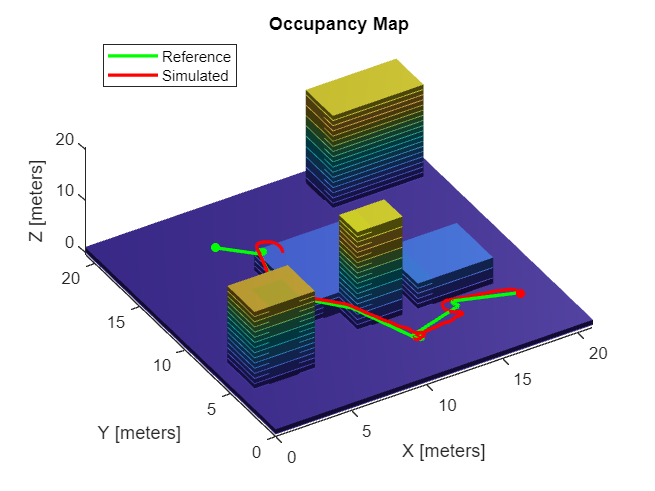

if (solnInfo.IsPathFound)
    figure("Name","OriginalPath")
    % Visualize the 3-D map
    show(omap)
    hold on
    scatter3(startPose(1),startPose(2),startPose(3),30,"red","filled")
    scatter3(goalPose(1),goalPose(2),goalPose(3),30,"green","filled")
    
    interpolatedPathObj = copy(pthObj);
    interpolate(interpolatedPathObj,1000)
    
    % Plot the interpolated path based on UAV Dubins connections
    hReference = plot3(interpolatedPathObj.States(:,1), ...
        interpolatedPathObj.States(:,2), ...
        interpolatedPathObj.States(:,3), ...
        "LineWidth",2,"Color","g");
    
    % Plot simulated UAV trajectory based on fixed-wing guidance model
    % Compute total time of flight and add a buffer
    timeToReachGoal = 1.05*pathLength(pthObj)/ss.AirSpeed;
    waypoints = interpolatedPathObj.States;
    [xENU,yENU,zENU] = SimulateUAV(waypoints,ss.AirSpeed,timeToReachGoal);
    hSimulated = plot3(xENU,yENU,zENU,"LineWidth",2,"Color","r");
    legend([hReference,hSimulated],"Reference","Simulated","Location","best")
    hold off
    view([-31 63])
end

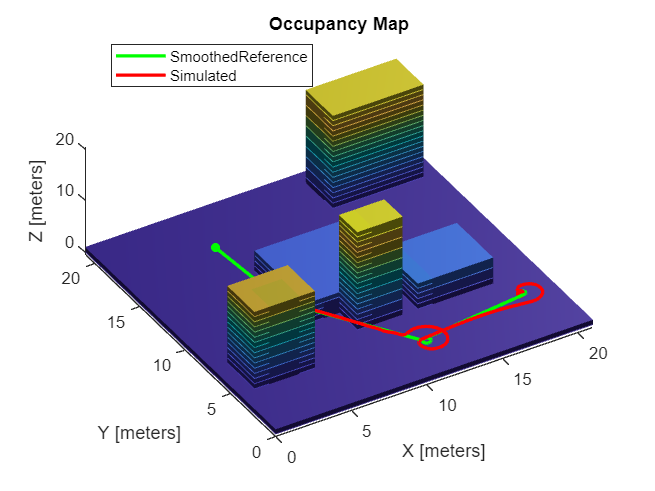

if (solnInfo.IsPathFound)
    smoothWaypointsObj = UAVPathSmoothing(ss,sv,pthObj);
    
    figure("Name","SmoothedPath")
    % Plot the 3-D map
    show(omap)
    hold on
    scatter3(startPose(1),startPose(2),startPose(3),30,"red","filled")
    scatter3(goalPose(1),goalPose(2),goalPose(3),30,"green","filled")
    
    interpolatedSmoothWaypoints = copy(smoothWaypointsObj);
    interpolate(interpolatedSmoothWaypoints,1000)
    
    % Plot smoothed path based on UAV Dubins connections
    hReference = plot3(interpolatedSmoothWaypoints.States(:,1), ...
        interpolatedSmoothWaypoints.States(:,2), ...
        interpolatedSmoothWaypoints.States(:,3), ...
        "LineWidth",2,"Color","g");
    
    % Plot simulated flight path based on fixed-wing guidance model
    waypoints = interpolatedSmoothWaypoints.States;
    timeToReachGoal = 1.05*pathLength(smoothWaypointsObj)/ss.AirSpeed;
    [xENU,yENU,zENU] = SimulateUAV(waypoints,ss.AirSpeed,timeToReachGoal);
    hSimulated = plot3(xENU,yENU,zENU,"LineWidth",2,"Color","r");
    
    legend([hReference,hSimulated],"SmoothedReference","Simulated","Location","best")
    hold off
    view([-31 63]);
end